# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

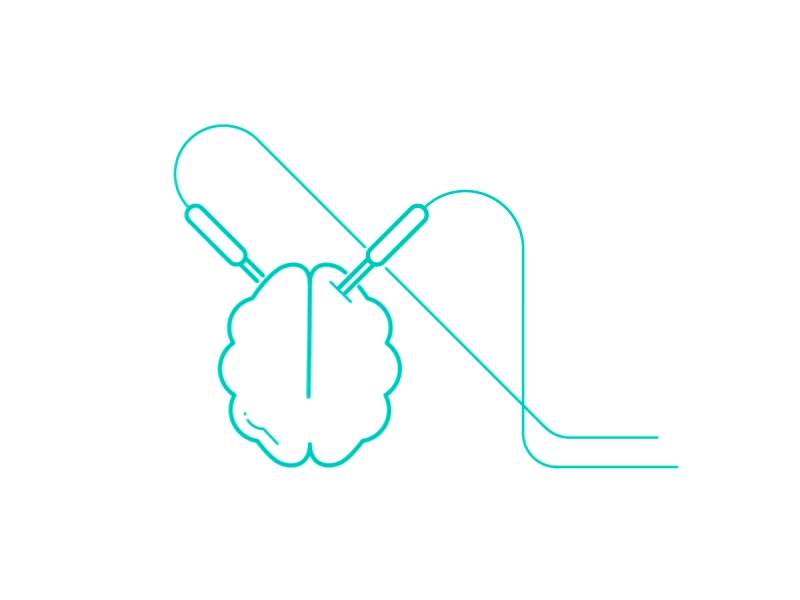

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\AkidaSoto\Desktop\Ne329\Module2\RawData'];
Deci.SubjectList = 'gui';
Deci.Step               = 5;
Deci.Folder.Version     = ['C:\Users\AkidaSoto\Desktop\Ne329\Module2\ProcessedData'];
Deci.Retroactive  = true;

## 1. Trial Definitions

Deci.DT.Starts     = {120};         %Cell Array of Markers for ETs Start.
Deci.DT.Ends       = {121};         %Cell Array of Markers for ETs End.
Deci.DT.Markers    = {[10 11]  [51 52 53] [81 82 83]};
%                       L/R       H        RCor
Deci.DT.Locks      = [14];
%                     S1 S2 R
Deci.DT.Toi        = [-2 3];
% Cell Array of Markers for Block Starts

## 2. PreProcessing Steps

Deci.PP = [];
Deci.PP.filter.bpfreq = [1 30];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.More.channel = {'TP10' 'TP9' 'PO3' 'PO4' 'O1' 'O2' 'PO7' 'PO8' 'P7' 'P8' 'TVEOG' 'BVEOG' 'RHEOG' 'LHEOG'};


Deci.ICA.do = false;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.Manual_Trial_Rejection = false;
Deci.Art.ShowArt =  true;

## 4. Analysis

Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.DownSample    = 500;

%CDA
  
Deci.Analysis.Channels = {'PO3' 'PO4' 'O1' 'O2' 'PO7' 'PO8' 'P7' 'P8'};
Deci.Analysis.Locks         = [1];                                                          % Which Lock to Analyze
Deci.Analysis.LocksTitle    = {'Delay Onset'};                      % Folder Title to save each Lock as
Deci.Analysis.Conditions    = {[10 11 51 81] [10 11 52 81] [10 11 53 81]};

Deci.Analysis.HemifieldFlip.do = true;
Deci.Analysis.HemifieldFlip.Markers = [10 11];

Deci.Analysis.CondTitle     = {'Set Size 1' 'Set Size 2' 'Set Size 3'};
Deci.Analysis.Version = [Deci.Folder.Version];
Deci.Analysis.ERP.do  = true;

Deci.Analysis.Toilim = [-2 3];
Deci.Analysis.Toi = [-.5 1.5];

## 5. Plotting

Deci.Plot.Version = [Deci.Analysis.Version];
Deci.Plot.Figures      = [true false false false];
Deci.Plot.Math         = {};           % Condition Math done after Bsl, Condition Indexes are appended on.
Deci.Plot.Draw         = {[1 2 3] [1] [2] [3]};                   % Cell array of Condition Index for each figure

Deci.Plot.Title        = {'Set Sizes All' 'Set Sizes 1' 'Set Sizes 2' 'Set Sizes 3'};          % Title for each figure
Deci.Plot.Subtitle     = {{'2' '4' '6'} {'2'} {'4'} {'6'}};     % Cell array of strings of subtitles for each Condition

Deci.Plot.BslRef = 'Delay Onset';
Deci.Plot.Lock =   'Delay Onset';
Deci.Plot.Bsl     = [-.2 0];

%Deci.Run.Freq =false;
Deci.Run.ERP =true;
Deci.Run.Extra = false;

Deci.Plot.GrandAverage = true;

Deci.Plot.Hemiflip.do = true;
Deci.Plot.Hemiflip.Type = 'Subtraction';

Deci.Plot.Topo.do    =false;
Deci.Plot.Topo.Toi     =[.2 .4];                   % Time of Interest
Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest

Deci.Plot.Wire.do    =true;
Deci.Plot.Wire.Channel =   {'PO3' 'PO4' 'O1' 'O2' 'PO7' 'PO8' 'P7' 'P8'};            % Channel of Interest
Deci.Plot.Wire.Toi     = [-.5 1.5];                   % Time of Interest

Deci.Plot.Bar.do    =true;
Deci.Plot.Bar.Toi     = [.3 .9];                    % Time of Interest
Deci.Plot.Bar.Channel =  {'PO3' 'PO4' 'O1' 'O2' 'PO7' 'PO8' 'P7' 'P8'};            % Channel of Interest

Deci.Plot.Stat.do = false; % Will only work if for large subject pools
if Deci.Plot.Stat.do
    Deci.Plot.Stat.Type = 'Anova/T-test';
    Deci.Plot.Stat.alpha = .05;
end


Deci_Backend(Deci);

Deci is running retroactive subjects

ans = logical
   1


Running Deci for 1 subjects
 
----------------------
 
Plotting ERP
Loading Plottor for Subject #1: swm21
the input is timelock data with 1 channels and 1001 timebins
the input is timelock data with 1 channels and 1001 timebins
the input is timelock data with 1 channels and 1001 timebins
the input is timelock data with 1 channels and 1001 timebins
the input is timelock data with 1 channels and 1001 timebins
the input is timelock data with 1 channels and 1001 timebins
the input is timelock data with 1 channels and 1001 timebins
the input is timelock data with 1 channels and 1001 timebins
the call to "ft_appendtimelock" took 0 seconds
the input is timelock data with 1 channels and 1001 timebins
the input is timelock data with 1 channels and 1001 timebins
the input is timelock data with 1 channels and 1001 timebins
the input is timelock data with 1 channels and 1001 timebins
the input is timelock data with 1 channels and 1001 timebins
the input is timelock data with 1 channels and 1001 ti